Set up kinematic links lengths. These are the lengths of the links in the diagram below

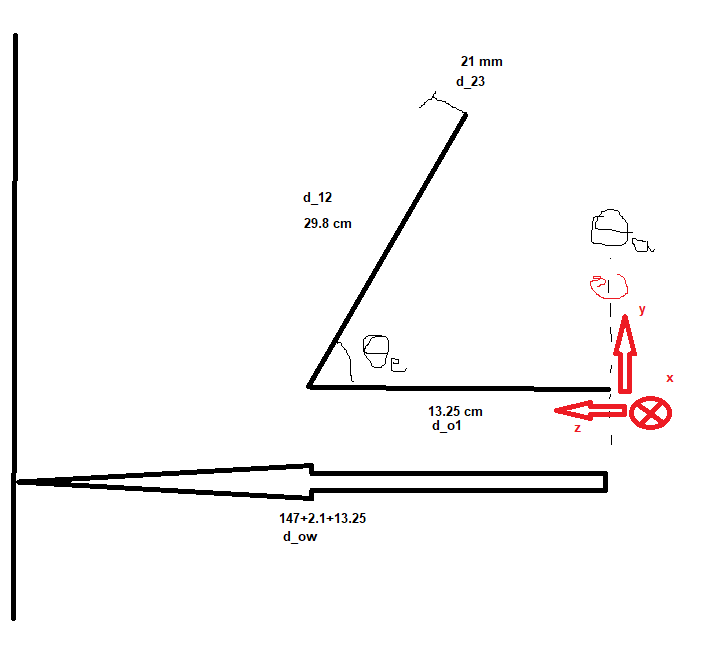

d_o1 = 13.25; % cm
d_12 = 29.8; % cm
d_23 = 2.1; % cm

d_ow = 147+d_o1+d_23; % cm

When the setpoint azimuth = 0, elevation = 90, the antenna **MUST** point directly at T14. 

% get elevation, azimuth angles to hit desired setpoint
targetx = 79.5;
targety = 105.5;
dirFirstVector = getAngles(targetx, targety, d_o1, d_12, d_23, d_ow);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


dx = 2;
dy = 3;

At this point, dirFirstVector will have the elevation and azimuth angles required to hit the target on the wall defined by targetx, targety. Now, you would enter these angles into the antenna and measure the distance between the laser and the target

% enter the setpoints into antenna

% "measure" the distance error with a ruler, then plug them in here
[angError] = getAngError(targetx, targety, dx, dy, d_o1, d_12, d_23, d_ow);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


angErrorDegrees = angError*180/pi

angErrorDegrees = 0.6340

The angular error is found by taking the angle between the desired laser vector and the real laser vector. To find this, there is an approximation made to find the intersection of these two vectors, which does not always exist. The term "distances" is the distance in cm from the intersection point and each of the vectors. Ideally, it will be 0, otherwise the angle technically doesn't exist. 

Another way to understand the error is to simply subtract the azimuth and elevation errors:

dirSecondVector = getAngles(targetx + dx, targety + dy, d_o1, d_12, d_23, d_ow);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


180/pi*(dirFirstVector - dirSecondVector)

ans =    -0.5665    0.5618


Looking at errors in this way could help identify problems specific to a certain axis.